# Numerical Integration Techniques

## Gaussian Quadrature

The first technique we will discuss is Gaussian Quadrature. This method approximates integrals over a given interval using orthogonal functions, typically over the interval [-1, 1] using the following formulation


$$$\int_{-1} ^1 f(x) \; dx \approx \sum_{i = 1} ^n w_i f(x_i)$$$


where the weights $w_i$ are given by


$$w_i = \frac{2}{(1 - x_i^2)P_n'(x_i)^2}$$


where $P_n(x)$ is the nth Legendre polynomial, a special type of polynomial which is orthogonal over the interval [-1, 1] by the $L^2$ norm, and $x_i$ represents the ith root of this nth Legendre polynomial. While there is a built-in function to calculate the Legendre polynomials (legendreP(n, x)), we can also calculate them recursively using the following relation:


$$P_n(x) = \frac1n[(2n-1)xP_{n - 1}(x) + (n-1)P_{n-2}(x)]$$


For reference, here is a plot of the first few Legendre polynomials over the interval [-1, 1]

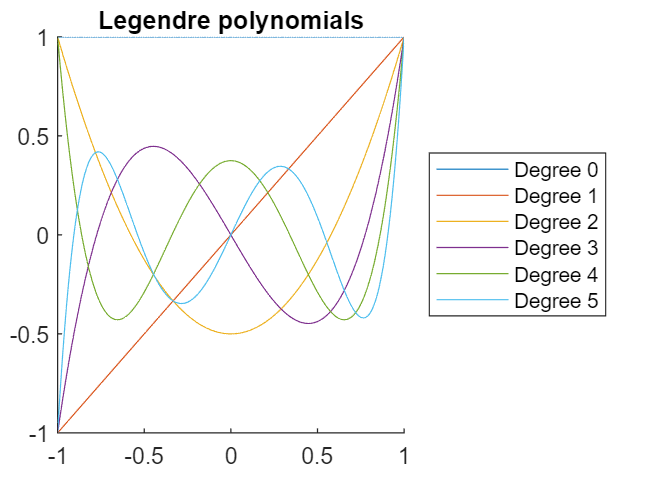

x = -1:0.01:1;
labels = num2cell("Degree " + string(0:5));
figure
hold on
for n = 0:5
    plot(x, legendreP(n, x))
end
title("Legendre polynomials")
legend(labels{:}, 'Location', 'eastoutside');
hold off

For the calculation of the Legendre polynomials, see the gaussQuad.m script. 

We can transform any integral over a real interval [a, b] into an integral from [-1, 1] using the following transformation:


$$\int_{a} ^b f(x) \; dx = \int_{-1} ^1 \frac{b - a}{2} f(\frac{b - a}{2} \xi + \frac{a+b}{2}) \; d\xi$$


For the implementation of this method, see gaussQuad.m. Here are some example evaluations.

% Integrating sin(x) from x = 0 to x = pi
y1 = @(x) sin(x);
disp("The integral of sin(x) from x = 0 to x = pi is")

The integral of sin(x) from x = 0 to x = pi is


gaussQuad(y1, 0, pi, 5)

ans = 2.0000


% Computing 0.5! = sqrt(pi)/2 using the Gamma function
y2 = @(x) x^0.5*exp(-x);
disp("0.5! is approximated to be")

0.5! is approximated to be


gaussQuad(y2, 0, 20, 15)

ans = 0.8889

disp("which is approximately sqrt(pi)/2 = 0.8862")

which is approximately sqrt(pi)/2 = 0.8862
